# [Facial Recognition](https://apmonitor.com/pds/index.php/Main/FacialRecognition)

Facial recognition is used in video surveillance such as on doorbell cameras, to tag subjects in social media posts, to unlock cell phones and computers, and in many other biometric applications. Marketers can use face detection with a webcam to predict the gender and age of the person to deliver targeted content. Cell phone camera apps include the feature to autofocus on a face or take the photo when a smile is detected. Keyless entry systems on an automobile may use facial recognition to unlock and enable the vehicle as well as adjust the seat position for the driver.

Students learn more if they have a personalized learning experience with their peers and the instructor. Instructors personalize the experience by learning things about each student including their name. Instructors also recognize when a student is absent or needs additional help. When a student is absent, an instructor often sends a message to check in and to give instructions for the missed content. Taking attendance each day and remembering to follow-up with an email can be a challenging task for teachers with a large class.

**Objective:** Develop a facial recognition system for participants in a class. Set up a camera to detect when an individual enters the classroom. Welcome them to the class with an audio message that uses their name. Record attendance with the name of the student and time that the student entered. If the student did not attend, send a text message or email with instructions for accessing the content for that day.

This is a challenging class project that requires the participation of all through collaborative programming and team work. Suggested roles are:

- Agile Development Leader

- Data Engineering

- Face Detection

- Classification

- Communication

There are many resources and tutorials online for the individual parts of the project. The challenge is to tie all of the pieces together and to tune the application for speed and accuracy. Below are some suggestions and references.

**Agile Development**

[**Agile software development**](https://en.wikipedia.org/wiki/Agile_software_development) is a software building process typically with small groups of 10 or less. The group plans for a sprint and holds daily meetings to discuss progress and obstacles. Burndown charts, task boards, and sprint plans are used to track progress instead of a Gantt chart. These metrics communicate progress and critical development items. With new software products, the focus is hyper-focused on a *Minimum Viable Product (MVP)*. Any extra features are saved for a future release.

The agile group leader enables collaboration through daily meetings and file sharing such as Box, Dropbox, or Google Drive. Code is best shared with simultaneous editing on [**Google Colab**](https://colab.research.google.com/) or through a repository hosted on [**GitHub**](https://github.com/) or [**GitLab**](https://about.gitlab.com/). The leader pulls together all contributions and tracks team effectiveness.

**Data Engineering**

Data engineering is retrieval, storage, and optimizing the flow of data. The responsibility of the data engineering team is to collect data from the camera, store multimedia content, split into train, validation, and test data, and build the data pipeline for the automated attendance system.

**Face Detection**

The face detection team explores methods to detect faces in a still frame or sequences of frames in a video stream. The face image is converted to a standard form for training and prediction. Each algorithm should be evaluated for real-time performance on the target hardware (Raspberry Pi, cloud computing, or laptop computer with GPU). Sample code is provided for [**MediaPipe Neural Networks**](https://mediapipe.dev/), Multi-task Cascaded Convolutional Neural Networks (MTCNN), and a Cascade Classifier. Other potential face detection algorithms are [**YOLO (You Only Look Once)**](https://viso.ai/deep-learning/yolov3-overview/) or [**YOLOR (You Only Learn Once Representation)**](https://viso.ai/deep-learning/yolor/).

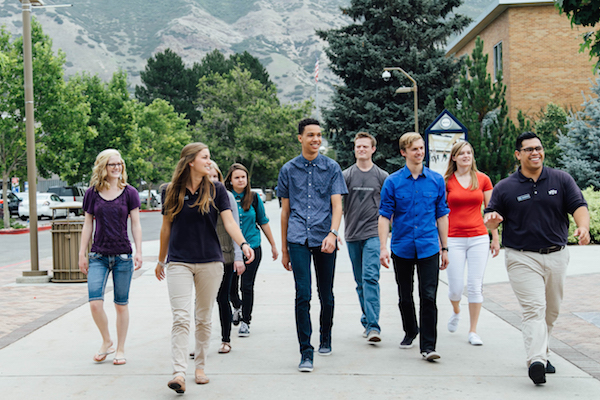

In MATLAB, you can learn more from the following links.

[Detecting Faces in Images » File Exchange Pick of the Week - MATLAB & Simulink (mathworks.com)](https://blogs.mathworks.com/pick/2014/03/14/detecting-faces-in-images/)

[Face, Age and Emotion Detection - File Exchange - MATLAB Central (mathworks.com)](https://www.mathworks.com/matlabcentral/fileexchange/71819-face-age-and-emotion-detection)

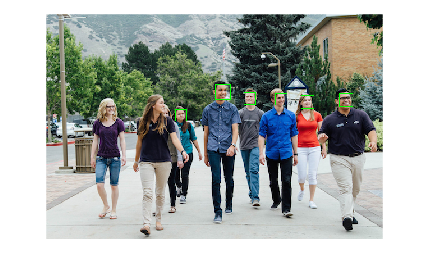

% Load image
url = 'http://apmonitor.com/pds/uploads/Main/students_walking.jpg';
filename = 'class.jpg';
outfilename = websave(filename,url);

faceDetector = vision.CascadeObjectDetector;
shapeInserter = vision.ShapeInserter('BorderColor','Custom','CustomBorderColor',[0 255 0]);

I = imread('class.jpg');

bbox = step(faceDetector,I);
% Draw boxes around detected faces and disply results
I_faces = step(shapeInserter,I,int32(bbox));
imshow(I_faces);

**Classification**

Train the classifier to detect specific individuals. Validate and test the classifier to quantify accuracy and evaluate the speed of classifiers with video stream.

**Communication**

*List of Students (*[***students.txt***](https://apmonitor.com/pds/uploads/Main/students.txt)*)*

`  First,Email`

`  Eric,eric@example.com`

`  Jane,jane@example.com`

To send an email, you need an account (user name and password) with an SMTP server address from the email provider. For BYU engineering students it is *mail.et.byu.edu* with the CAEDM user name and password. You must be on a campus IP address or connected through the VPN to send emails from this STMP server.

The following code will only work if you complete the following steps

1. Download the following JAR file: [https://github.com/javaee/javamail/releases/download/JAVAMAIL-1_6_2/javax.mail.jar](https://protect-us.mimecast.com/s/0HtbCR6XrRIA7pkNT9bYma?domain=github.com)

2. Rename this JAR file to mail.jar.

3. Replace *<matlabroot>/java/jarext/axis2/mail.jar* with the downloaded JAR file.

4. Restart MATLAB.

5. Add the following line to the your MATLAB code:

`        props.setProperty('mail.smtp.ssl.protocols', "TLSv1.2");`

6. Execute your MATLAB code.

email = input("Enter email address of the sender: ","s");
username = input("Enter email user name: ","s"); 
smtp_server = input("Enter SMTP server address: ","s");
password = getPasswordNET;

% Set up email preferences
props = java.lang.System.getProperties;
props.setProperty('mail.smtp.ssl.protocols', "TLSv1.2");
props.setProperty('mail.smtp.auth','true');
props.setProperty('mail.smtp.starttls.enable','true');

% Set up to send the email
setpref('Internet','SMTP_Server',smtp_server);
setpref('Internet','E_mail',email);
setpref('Internet','SMTP_Username',username);
setpref('Internet','SMTP_Password',password);
% props.setProperty('mail.debug','true');

messageBody = sprintf('We missed you in class today. I hope you are doing well. ');
messageBody = sprintf('%s Today we worked on the project for facial recognition.', messageBody);
messageBody = sprintf('%s\n\n Best regards,', messageBody);
messageBody = sprintf('%s\n John Hedengren', messageBody);
messageBody = sprintf('%s\n Brigham Young University', messageBody);

sendmail(email,'Hello! We missed you today',messageBody);

DEBUG: JavaMail version 1.6.2
DEBUG: successfully loaded resource: /META-INF/javamail.default.address.map
DEBUG: getProvider() returning javax.mail.Provider[TRANSPORT,smtp,com.sun.mail.smtp.SMTPTransport,Oracle]
DEBUG SMTP: need username and password for authentication
DEBUG SMTP: protocolConnect returning false, host=mail.et.byu.edu, user=jacob, password=<null>
DEBUG SMTP: useEhlo true, useAuth true
DEBUG SMTP: trying to connect to host "mail.et.byu.edu", port 25, isSSL false
220 postal1.et.byu.edu ESMTP Postfix
DEBUG SMTP: connected to host "mail.et.byu.edu", port: 25
EHLO Teancum.app.byu.edu
250-postal1.et.byu.edu
250-PIPELINING
250-SIZE 26214400
250-VRFY
250-ETRN
250-STARTTLS
250-ENHANCEDSTATUSCODES
250-8BITMIME
250-DSN
250 CHUNKING
DEBUG SMTP: Found extension "PIPELINING", arg ""
DEBUG SMTP: Found extension "SIZE", arg "26214400"
DEBUG SMTP: Found extension "VRFY", arg ""
DEBUG SMTP: Found extension "ETRN", arg ""
DEBUG SMTP: Found extension "STARTTLS", arg ""
DEBUG SMTP: Found ex

Supporting Functions

function pass = getPasswordNET()
    %# password return value
    pass = '';

    %# hidden figure used to wait for button press
    fig = figure('Visible','off', ...
        'IntegerHandle','off', 'HandleVisibility','off');

    %# create and show the Windows Forms GUI
    [handles,lh] = InitializeComponents();
    handles.frm.Show();

    %# block execution until figure is closed
    waitfor(fig)

    %# remove the listeners
    delete(lh);

    return;

    %# create GUI
    function [handles,lh] = InitializeComponents()
        %# import assembly
        NET.addAssembly('System.Windows.Forms');

        %# form
        frm = System.Windows.Forms.Form();
        frm.SuspendLayout();

        %# textbox
        tb = System.Windows.Forms.TextBox();
        tb.Dock = System.Windows.Forms.DockStyle.Fill;
        tb.Text = '';
        tb.PasswordChar = '*';
        tb.MaxLength = 14;

        %# button
        bt = System.Windows.Forms.Button();
        bt.Dock = System.Windows.Forms.DockStyle.Bottom;
        bt.Text = 'Submit';

        %# setup the form
        frm.Text = 'Password';
        frm.ClientSize = System.Drawing.Size(250, 40);
        frm.Controls.Add(tb);
        frm.Controls.Add(bt);
        frm.ResumeLayout(false);
        frm.PerformLayout();

        %# add event listeners
        lh(1) = addlistener(bt, 'Click', @onClick);
        lh(2) = addlistener(frm, 'FormClosing', @onClose);

        %# return handles structure
        handles = struct('frm',frm, 'tb',tb, 'bt',bt);
    end

    %# event handlers
    function onClick(~,~)
        %# get password from textbox
        pass = char(handles.tb.Text);

        %# close form
        handles.frm.Close();
    end
    function onClose(~,~)
        %# delete hidden figure (to unblock and return from function)
        close(fig)
    end
end